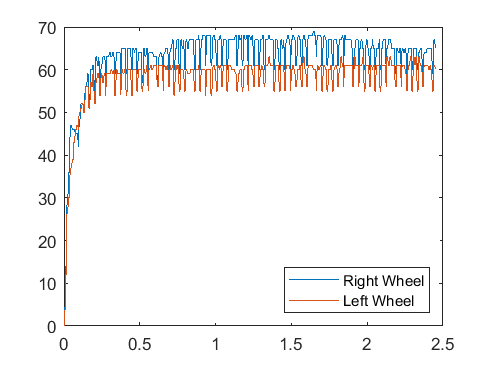

clear
load wheel_velocities_trial_1.mat
wheel_data = data;

left_wheel = wheel_data(:,1);
right_wheel = wheel_data(:,2);
time = 0:0.005:0.005*(length(right_wheel)-1);

plot(time, left_wheel); hold on
plot(time, right_wheel); hold off
legend("Right Wheel", "Left Wheel", Location="southeast")


syms s t K tau 
M(s) = (K/tau)/(s+1/tau)

$$M(s) = \frac{K}{\tau \,\left(s+\frac{1}{\tau }\right)}$$

step(s) = 200/s

$$step(s) = \frac{200}{s}$$

m(t) = ilaplace(M(s)*step(s))

$$m(t) = 200\,K-200\,K\,{\mathrm{e}}^{-\frac{t}{\tau }}$$

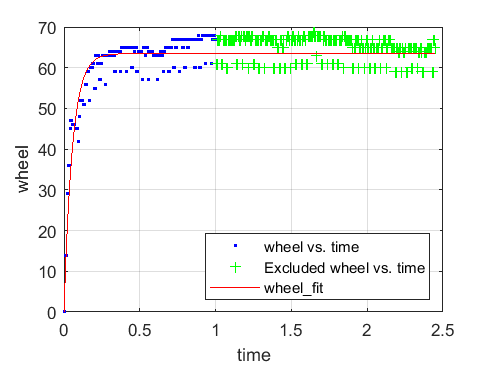


[left_fitresult, left_gof] = wheel_fit(time, left_wheel);

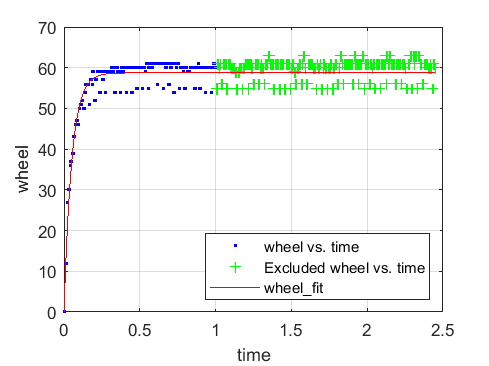

left_k = left_fitresult.k;
left_tau = left_fitresult.tau;

[right_fitresult, right_gof] = wheel_fit(time, right_wheel);

right_k = right_fitresult.k;
right_tau = right_fitresult.tau;


